# **DSP HW2**

**By: 106061151 劉安得**

## 1. (a)


$$y\left\lbrack n\right\rbrack =\sum_{k\;=\;-\infty }^{\infty } x\left\lbrack k\right\rbrack h\left\lbrack n-k\right\rbrack$$



$$x\left\lbrack n\right\rbrack =h\left\lbrack n\right\rbrack ={0\ldotp 9}^n u\left\lbrack n\right\rbrack$$



$$\begin{array}{l}
y\left\lbrack n\right\rbrack =\sum_{k\;=\;-\infty }^{\infty } {0\ldotp 9}^k u\left\lbrack k\right\rbrack {0\ldotp 9}^{n-k} u\left\lbrack n-k\right\rbrack ={0\ldotp 9}^n \sum_{k\;=\;-\infty }^{\infty } u\left\lbrack k\right\rbrack u\left\lbrack n-k\right\rbrack \\
={0\ldotp 9}^n \sum_{k\;=0}^{\infty } u\left\lbrack n-k\right\rbrack ={0\ldotp 9}^n \sum_{k\;=0}^n 1={0\ldotp 9}^n \left(n+1\right)
\end{array}$$


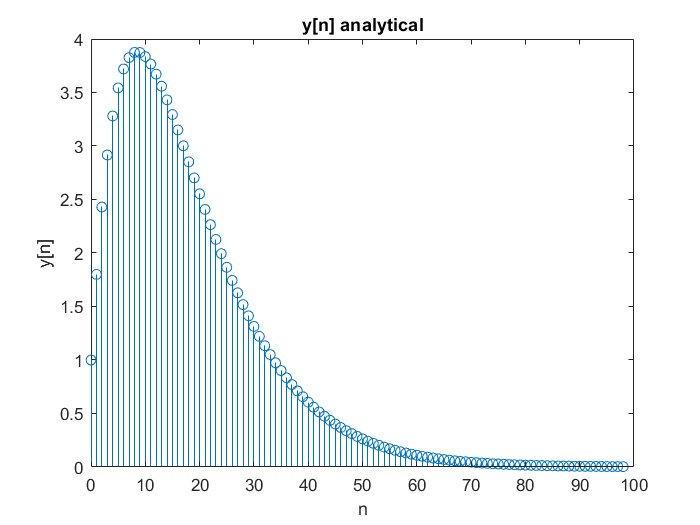

%Prob. 1(a)
n1 = 0:98;
yn1 = 0.9.^n1.*(n1+1);

figure
stem(n1, yn1)
title('y[n] analytical')
xlabel('n')
ylabel('y[n]')

## 1. (b)

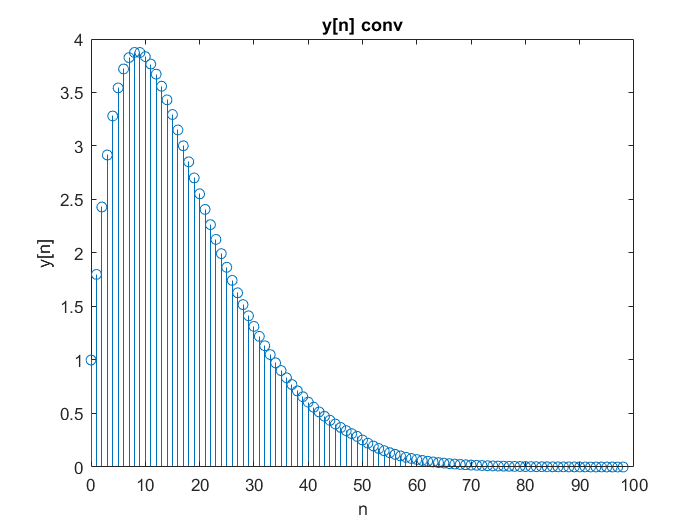

%Prob. 1(b)
n2 = 0:49;
xn2 = 0.9.^n2;
hn2 = 0.9.^n2;
yn2 = conv(xn2, hn2);
ny=0:length(yn2)-1;

figure
stem(ny, yn2)
title('y[n] conv')
xlabel('n')
ylabel('y[n]')

## 1. (c)

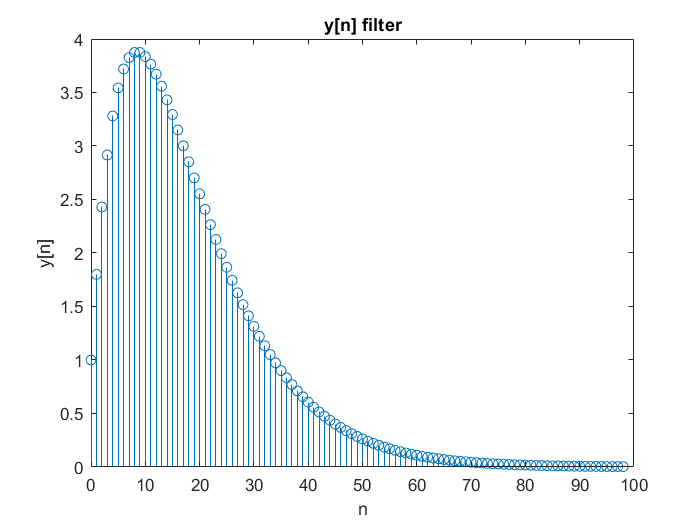

%Prob. 1(c)
n3 = 0:98;
xn3 = 0.9.^n3;
hn3 = 0.9.^n3;
yn3 = filter(hn3, 1, xn3);

figure
stem(n3, yn3)
title('y[n] filter')
xlabel('n')
ylabel('y[n]')

## 1. (d)

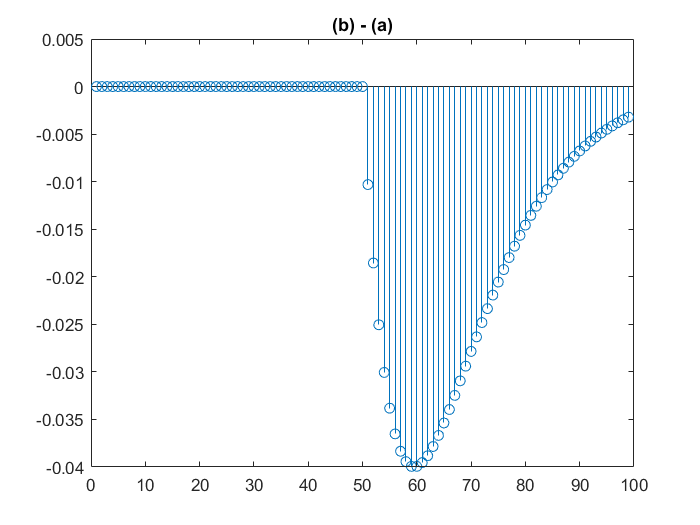

%Prob. 1(d)
dy1 = yn2 - yn1;
dy2 = yn3 - yn1;

figure
stem(dy1)
title('(b) - (a)')

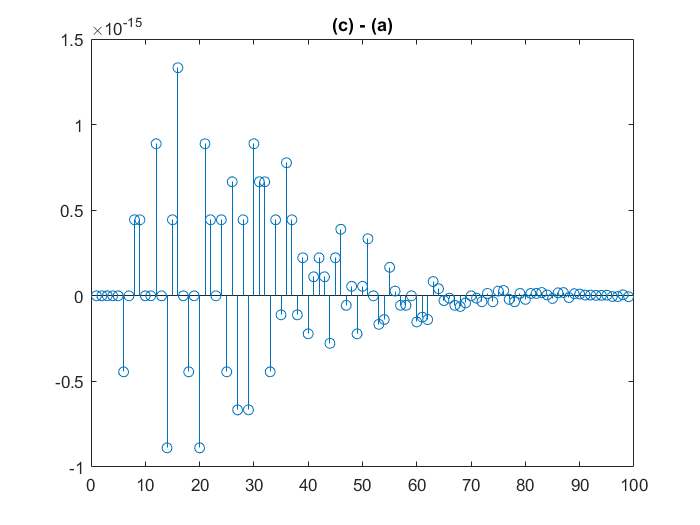

figure
stem(dy2)
title('(c) - (a)')

由圖可知，(c)跟(a)比較接近，可能是因為算conv時，我們只取了前50個sample，而filter則是用跟output一樣大小的99個sample來做計算

## 2. (a)


$$A_y =\sum_n y\left\lbrack n\right\rbrack =\sum_n \sum_{k\;=\;-\infty }^{\infty } x\left\lbrack k\right\rbrack h\left\lbrack n-k\right\rbrack =\sum_{k\;=\;-\infty }^{\infty } x\left\lbrack k\right\rbrack \sum_n h\left\lbrack n-k\right\rbrack =\sum_{k\;=\;-\infty }^{\infty } x\left\lbrack k\right\rbrack \sum_n h\left\lbrack n\right\rbrack =A_x A_h$$


## 2. (b)

%Prob. 2(b)
x = sin(2*pi*0.01*(0:100)) + 0.05*randn(1,101);
h = ones(1,5);
y1 = conv(x, h);
Ax = sum(x)

Ax = -0.7206

Ah = sum(h)

Ah = 5

Ay = sum(y1)

Ay = -3.6030

AxAh = Ax*Ah

AxAh = -3.6030

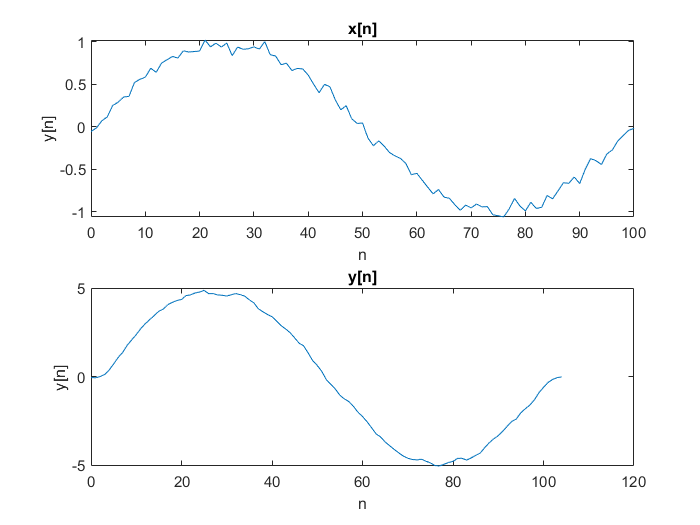

nx=0:length(x)-1;
ny=0:length(y1)-1;

figure
subplot(2, 1, 1), plot(nx, x)
title('x[n]')
xlabel('n')
ylabel('y[n]')
subplot(2, 1, 2), plot(ny, y1)
title('y[n]')
xlabel('n')
ylabel('y[n]')

check Ay = Ax*Ah is true

## 2. (c)

%Prob. 2(c)
h_normalized = h/Ah;
y2 = conv(x, h_normalized);
Ax = sum(x)

Ax = -0.7206

Ah = sum(h_normalized)

Ah = 1

Ay = sum(y2)

Ay = -0.7206

AxAh = Ax*Ah

AxAh = -0.7206

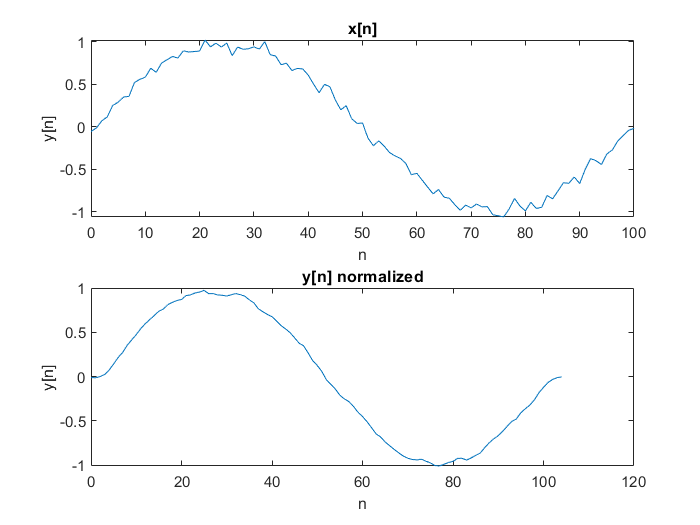

nx=0:length(x)-1;
ny=0:length(y2)-1;

figure
subplot(2, 1, 1), plot(nx, x)
title('x[n]')
xlabel('n')
ylabel('y[n]')
subplot(2, 1, 2), plot(ny, y2)
title('y[n] normalized')
xlabel('n')
ylabel('y[n]')

## 2. (d)

y 被 normalized，本來 in part (b)，x[n] 的 peak to peak 值跟 y[n] 差很多，但 in part (c)，兩者的 peak to peak 值便很接近

## 3. (a)


$$\begin{array}{l}
X\left(z\right)=\frac{1}{1-z^{-1} }\\
Y\left(z\right)=\frac{2}{1-\frac{1}{3}z^{-1} }=H\left(z\right)X\left(z\right)\\
H\left(z\right)=\frac{2\left(1-z^{-1} \right)}{1-\frac{1}{3}z^{-1} }
\end{array}$$


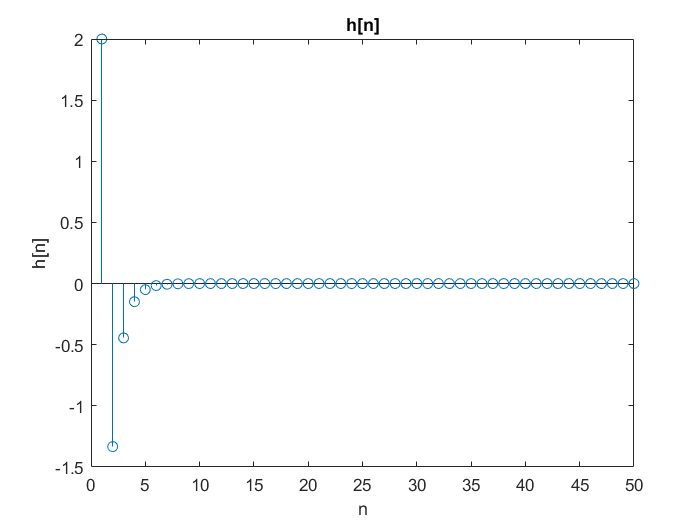

%Prob. 3(a)
b=[2 -2];
a=[1 -1/3];
delta = [1, zeros(1, 49)];
hn1 = filter(b, a, delta);

figure
stem(hn1)
title('h[n]')
xlabel('n')
ylabel('h[n]')

## 3. (b)

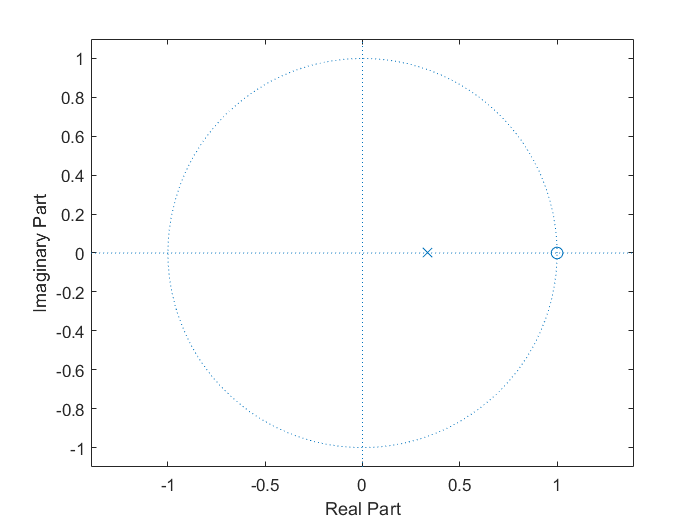

%Prob. 3(b)
figure
zplane(b, a)

## 3. (c)

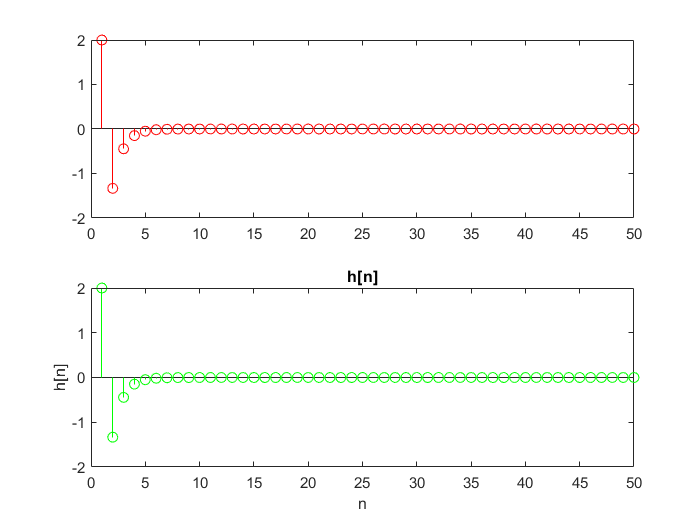

%Prob. 3(c)
hn2 = impz(b, a, 50);

figure
subplot(2, 1, 1)
stem(hn1, 'r')
subplot(2, 1, 2)
stem(hn2, 'g')
title('h[n]')
xlabel('n')
ylabel('h[n]')

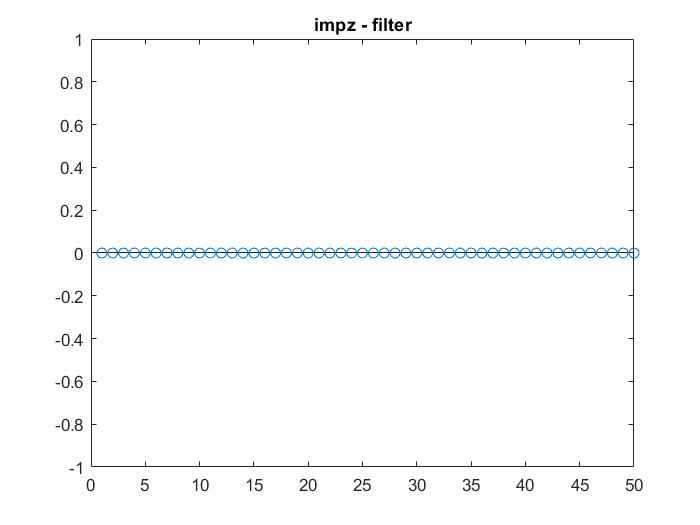


dh = hn2' - hn1;
figure
stem(dh)
title('impz - filter')

impz is as same as filter !!!

## 3. (d)

%Prob. 3(d)
[r, p, k] = residuez(b, a);
r, p, k

r = -4

p = 0.3333

k = 6


$$\begin{array}{l}
H\left(z\right)=-\frac{4}{1-\frac{1}{3}z^{-1} }+6\\
h\left\lbrack n\right\rbrack =-4*{\frac{1}{3}}^n u\left\lbrack n\right\rbrack +6\delta \left\lbrack n\right\rbrack 
\end{array}$$


## 4.


$$H\left(z\right)=\frac{z\left(b_0 z+b_1 \right)}{z^2 +a_1 z+a_2 }$$


because of real and equal poles


$$\begin{array}{l}
D=\sqrt{{a_1 }^2 -4a_2 }=0\\
{a_1 }^2 =4a_2 \\
H\left(z\right)=\frac{z\left(b_0 z+b_1 \right)}{z^2 +a_1 z+\frac{{a_1 }^2 }{4}}
\end{array}$$


the pole is $\frac{{-a}_1 }{2}$

## 4. (a)

when $\left|\frac{{-a}_1 }{2}\right|<1$, that is $\left|a_1 \right|<2$, the system is stable

whem $\left|a_1 \right|\ge 2$, tje system is unstable

## 4. (b)

when $a_1 \;<-2$, the shape is Growing exponential

when $a_1 =-2$, the shape is Unit Step

when $-2<a_1 <0$, the shape is Decaying exponential

when $0<a_1 <2$, the shape is Decaying alternating exponential

when $a_1 =2$, the shape is Unit alternating Step

when $a_1 >2$, the shape is Growing alternating exponential

%Prob. 4
%let b0 = 1, b1 = 1
b0 = 1;
b1 = -1;
n = 0:49;

%when a1 < -2, e.g. a1 = -3
a1 = -3;
Hz = z*(b0*z+b1)/(z^2+(a1)*z+(a1^2)/4);

Undefined function or variable 'z'.

hn1 = iztrans(Hz, n);
figure
stem(n, hn1)
title('Growing exponential')
xlabel('n')
ylabel('h[n]')

%when a1 = -2
a1 = -2;
Hz = z*(b0*z+b1)/(z^2+(a1)*z+(a1^2)/4);
hn2 = iztrans(Hz, n);
figure
stem(hn2)
title('Unit Step')
xlabel('n')
ylabel('h[n]')

b0 = 1;
b1 = 1;

%when 0 > a1 > -2, e.g. a1 = -1
a1 = -1;
Hz = z*(b0*z+b1)/(z^2+(a1)*z+(a1^2)/4);
hn3 = iztrans(Hz, n);
figure
stem(hn3)
title('Decaying exponential')
xlabel('n')
ylabel('h[n]')

%when 2 > a1 > 0, e.g. a1 = 1
a1 = 1;
Hz = z*(b0*z+b1)/(z^2+(a1)*z+(a1^2)/4);
hn4 = iztrans(Hz, n);
figure
stem(hn4)
title('Decaying alternating exponential')
xlabel('n')
ylabel('h[n]')

%when a1 = 2, e.g. a1 = 2
a1 = 2;
Hz = z*(b0*z+b1)/(z^2+(a1)*z+(a1^2)/4);
hn5 = iztrans(Hz, n);
figure
stem(hn5)
title('Unit alternating Step')
xlabel('n')
ylabel('h[n]')

%when a1 > 2, e.g. a1 = 3
a1 = 3;
Hz = z*(b0*z+b1)/(z^2+(a1)*z+(a1^2)/4);
hn6 = iztrans(Hz, n);
figure
stem(hn6)
title('Growing alternating exponential')
xlabel('n')
ylabel('h[n]')

## 5. (a)


$$\begin{array}{l}
y\left\lbrack n\right\rbrack =2\mathrm{cos}\left(\omega_0 \right)y\left\lbrack n-1\right\rbrack -y\left\lbrack n-2\right\rbrack \\
y\left\lbrack -1\right\rbrack =0,y\left\lbrack -2\right\rbrack =-A\;\mathrm{sin}\left(\omega_0 \right)
\end{array}$$


Apply One-Sided Z-Transform of Two-Order LCCDE


$$\begin{array}{l}
a_1 =-2\mathrm{cos}\left(\omega_0 \right),a_2 =1\\
Y^+ \left(z\right)=\frac{-y\left\lbrack -1\right\rbrack z^{-1} +2\mathrm{cos}\left(\omega_0 \right)y\left\lbrack -1\right\rbrack -y\left\lbrack -2\right\rbrack }{1-2\;\mathrm{cos}\left(\omega_0 \right)z^{-1} +z^{-2} }=\frac{A\;\mathrm{sin}\left(\omega_0 \right)}{1-2\mathrm{cos}\left(\omega_0 \right)z^{-1} +z^{-2} }=\frac{A\;\mathrm{sin}\left(\omega_0 \right)z^{-1} }{1-2\mathrm{cos}\left(\omega_0 \right)z^{-1} +z^{-2} }z\\
y\left\lbrack n\right\rbrack =A\;\mathrm{sin}\left(\omega_0 \left(n+1\right)\right)u\left\lbrack n\right\rbrack 
\end{array}$$


## 5. (b)

%Prob. 5(b)
x = zeros(1,50);
b = [0 0 0];
a = [1 -2*cos(0.1*pi) 1];
yic = [0 -2*sin(0.1*pi)];
xic = [0 0];
zic = filtic(b, a, yic, xic);
y = filter(b, a, x, zic);

figure
stem(y)
title('y[n]')
xlabel('n')
ylabel('y[n]')

n = 0:49;
y1 = 2.*sin((n+1)*0.1*pi).*heaviside(n);

figure
stem(n, y1)
title('y[n]')
xlabel('n')
ylabel('y[n]')

## 6(a)

%Prob. 6(a)
n = 0:49;
x = cos(2*pi/100*n);
c1 = dtfs0(x);
c2 = dtfs(x);

figure
stem(abs(c1))
title('dtfs0')

figure
stem(abs(c2))
title('dtfs')

## 6(b)

%Prob. 6(b)
k = 0:49;
c = cos(2*pi/100*k);
x1 = idtfs0(c);
x2 = idtfs(c);

figure
stem(abs(x1))
title('idtfs0')

figure
stem(abs(x2))
title('idtfs')

## 7. (a)

%Prob. 7(a)
n = 0:4;
x1 = 4.*cos(1.2*pi*n + pi/3) + 6.*sin(0.4*pi*n - pi/6);
c1 = dtfs(x1);

figure
subplot(2, 1, 1)
stem(abs(c1))
title('magnitude of X1[k]')
xlabel('k')
ylabel('|X[k]|')
subplot(2, 1, 2)
stem(angle(c1))
title('phase of X1[k]')
xlabel('k')
ylabel('∠X[k]')

## 7. (b)

%Prob. 7(b)
x2 = [1,1,0,1,1,1,0,1];
c2 = dtfs(x2);

figure
subplot(2, 1, 1)
stem(abs(c2))
title('magnitude of X2[k]')
xlabel('k')
ylabel('|X[k]|')
subplot(2, 1, 2)
stem(angle(c2))
title('phase of X2[k]')
xlabel('k')
ylabel('∠X[k]')

## 7. (c)

%Prob. 7(c)
n = 0:11;
x3 = 1-sin(pi/4*n);
c3 = dtfs(x3);

figure
subplot(2, 1, 1)
stem(abs(c3))
title('magnitude of X3[k]')
xlabel('k')
ylabel('|X[k]|')
subplot(2, 1, 2)
stem(angle(c3))
title('phase of X3[k]')
xlabel('k')
ylabel('∠X[k]')

## 8. (a)

%Prob. 8(a)
x=[1 1 1]; % n=-1,0,1
om=linspace(-pi, pi, 60);
X1=dtft12(x, -1, om);
X2=freqz(x, 1, om);

figure
subplot(2,2,1);
stem(abs(X1))
title('magnitude of X1')
xlabel('k')
ylabel('|X1|')

subplot(2,2,2);
stem(abs(X2))
title('magnitude of X2')
xlabel('k')
ylabel('|X2|')

subplot(2,2,3);
stem(angle(X1))
title('phase of X1')
xlabel('k')
ylabel('∠X1')

subplot(2,2,4);
stem(angle(X2))
title('phase of X2')
xlabel('k')
ylabel('∠X2')

## 8. (b)

magnitude大小一樣，但phase有些差別

因為 dtft12 是用快速傅立葉轉換，所以跟一般的 z transform 相比 phase有些扭曲

## 9.

img = imread('DSP.png');
figure
imshow(img);
imwrite(img, 'DSP0.png');

## 9. (a)

%Prob. 9(a)
img_double = double(img);
h = ones(5, 5)/25;
img1 = conv2(img_double, h);
figure
imshow(img1);
imwrite(img1, 'DSP1.png');

變細了，因為他是抓附近5*5平均，所以黑色會變細

## 9. (b)

%Prob. 9(b)
h1 = [1 0 -1; 2 0 -2; 1 0 -1];
img2 = conv2(img_double, h1);
img2
img2 = abs(img2);
img2 = uint8(img2);
figure
imshow(img2);
imwrite(img2, 'DSP2.png');

h2 = h1';
img3 = conv2(img_double, h2);
img3
img3 = abs(img3);
img3 = uint8(img3);
figure
imshow(img3);
imwrite(img3, 'DSP3.png');

白線水平跟垂直的差別，因為他們的filter剛好行列互換

## 9. (c)

%Prob. 9(c)
img4 = filter2(h1, img_double);
img4
img4 = abs(img4);
img4 = uint8(img4);
figure
imshow(img4);
imwrite(img4, 'DSP4.png');

img5 = filter2(h2, img_double);
img5
img5 = abs(img5);
img5 = uint8(img5);
figure
imshow(img5);
imwrite(img5, 'DSP5.png');

邊界值正負號不同，以及filter邊界誤差值比較少

## 10.

[y,Fs] = audioread('handel.wav');
playerObj = audioplayer(y, Fs);
play(playerObj);
audiowrite('handel0.wav', y, Fs);

## 10. (a)

%Prob. 10(a)
y1 = y(1:2:end);
playerObj = audioplayer(y1, Fs/2);
play(playerObj);
audiowrite('handel1.wav', y1, Fs/2);

## 10. (b)

%Prob. 10(b)
y2 = y(1:4:end);
playerObj = audioplayer(y2, Fs/4);
play(playerObj)
audiowrite('handel2.wav', y2, Fs/4);

## 10. (c)

隨著sampling rate 降低，聲音變得越來越模糊，音質變得越來越差，感覺上解析度降低了

檔案大小變小